## Autor: Guillermo Fernando Regodón Harkness

## Creamos un array con una señal cuadrada de ejemplo

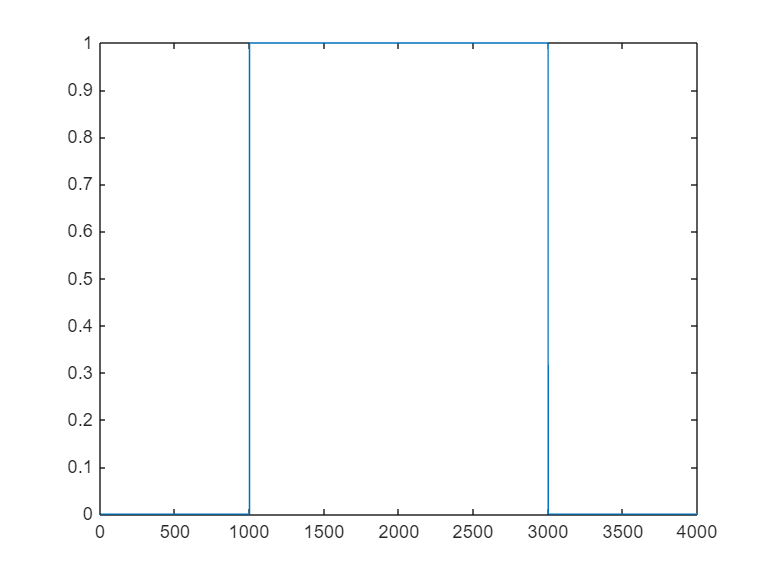

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];

% Creamos un objeto para estudiar la señal cuadrada
fft_cuad = Fftreal(x);
fft_cuad.plotx();

## Creamos un array de frecuencias con tres armónicos de ejemplo

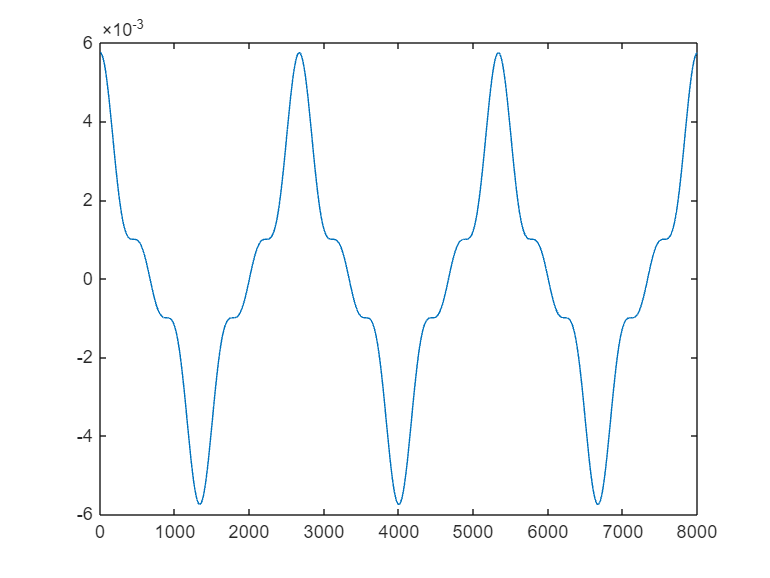

f = [zeros(1, 4000)];
f(3) = 15;
f(9) = 5;
f(15) = 3;

% Creamos un objeto para estudiar la señal de los tres armónicos
fft_armo = Fftreal([], f);
fft_armo.plotx();

## DELAY

### PRIMER USO, todas las frecuencias se retrasan igual

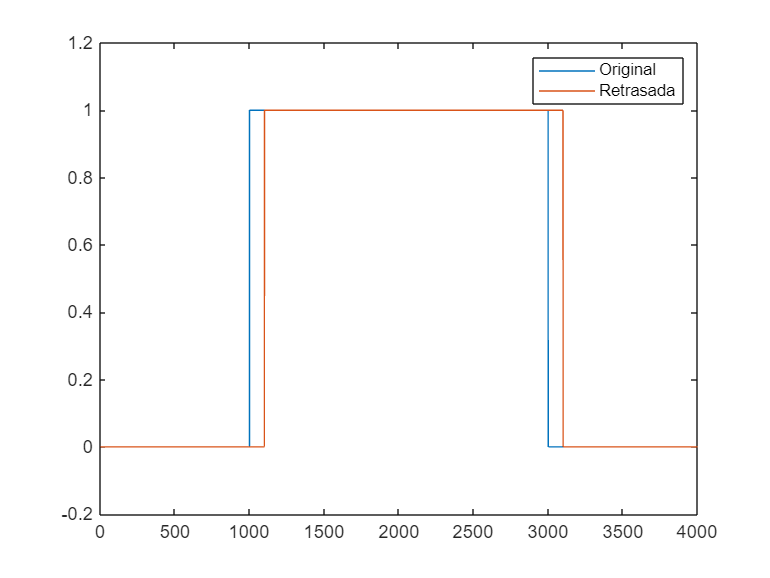

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
d = 100;
fftn = fft.delay(d);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Retrasada"])

### SEGUNDO USO, algunas frecuencias se retrasan más que otras

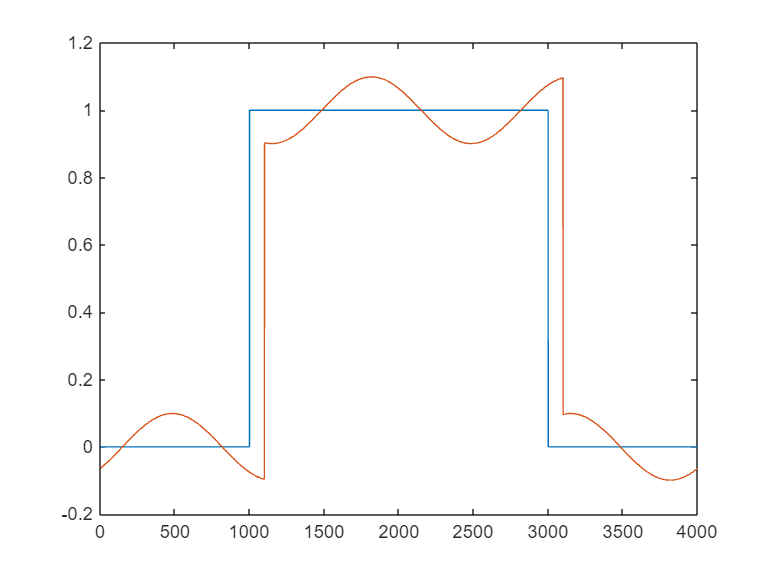

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
d = 100*ones(size(fft.freq()));
d(3) = 200;
fftn = fft.delay(d);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Retrasada"])

## BETA

### PRIMER USO, sin distorsión de fase.

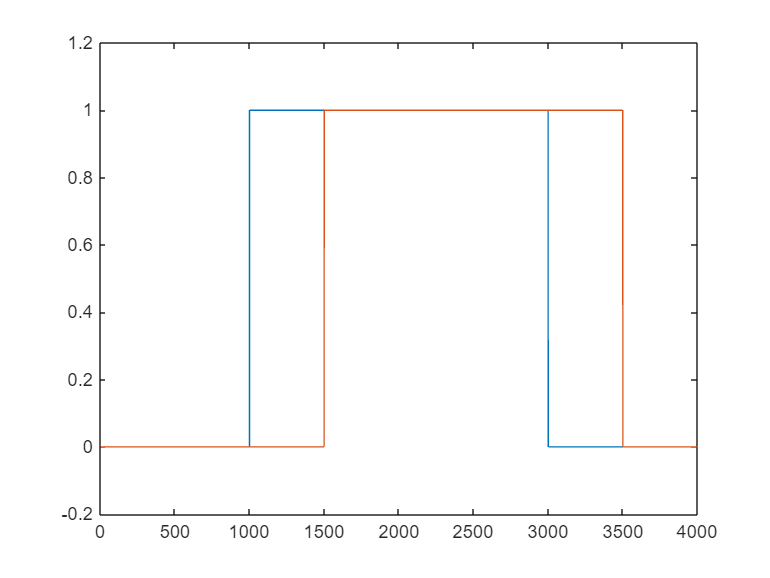

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
beta = fft.freq()*10;
l = 50;
fftn = fft.betal(beta, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

### SEGUNDO USO, con distorsión de fase, frecuencia de corte 0.0015

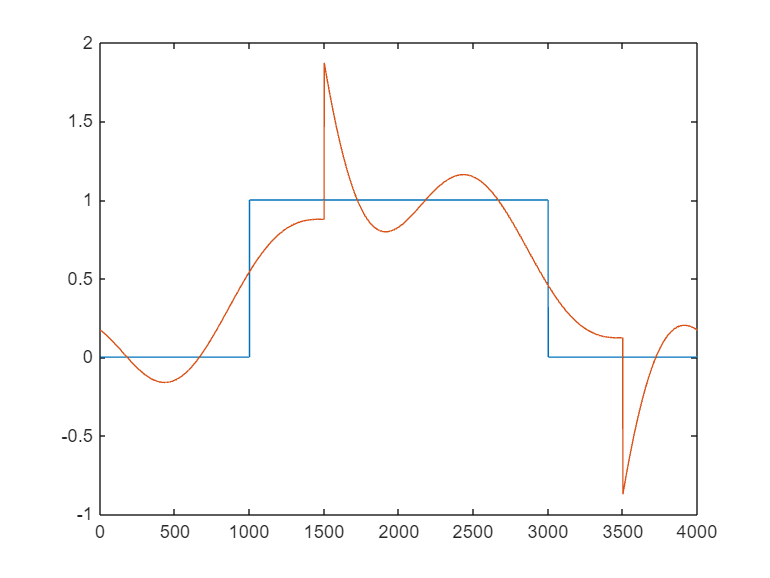

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
freq = fft.freq();
beta = real(sqrt(-freq(3)^2 + freq.^2)*10);
l = 50;
fftn = fft.betal(beta, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

## ALFA

### PRIMER USO, sin distorsión de amplitud.

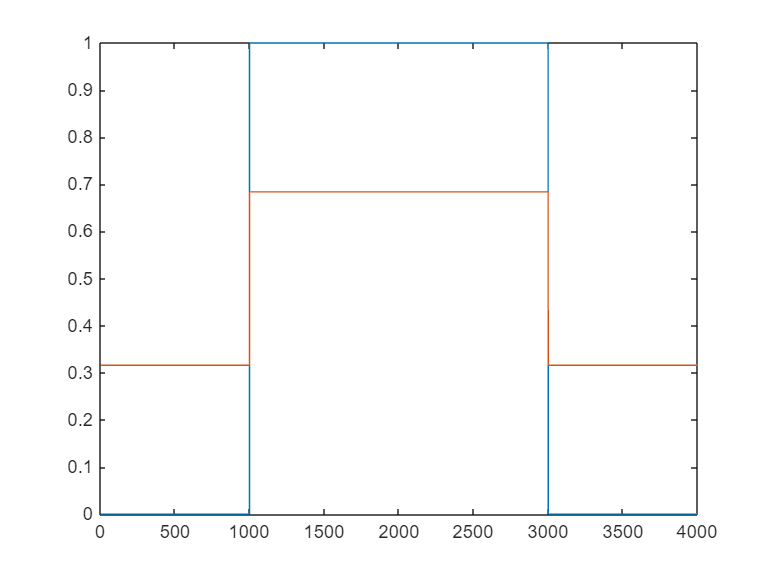

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
alfa = 0.02;
l = 50;
fftn = fft.alfa(alfa, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

### SEGUNDO USO, con distorsión de fase

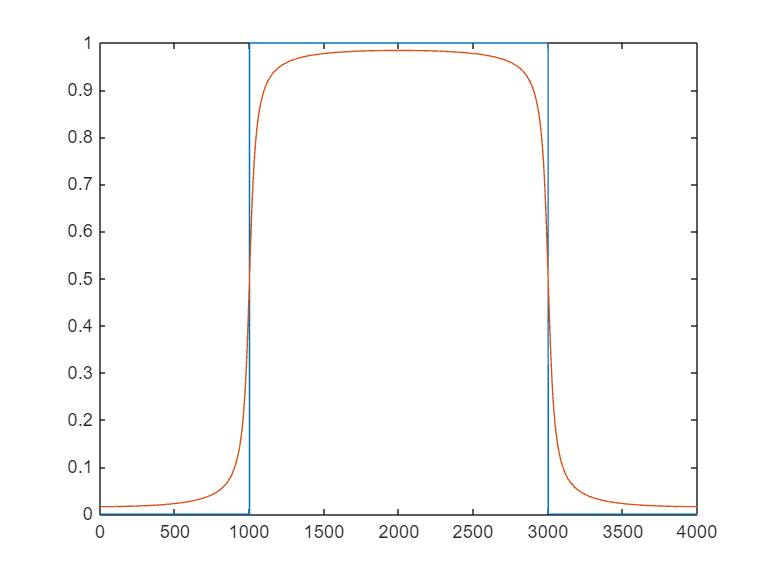

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
freq = fft.freq();
alfa = freq*2;
l = 50;
fftn = fft.alfa(alfa, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

## VELOC

### PRIMER USO, sin distorsión de fase.

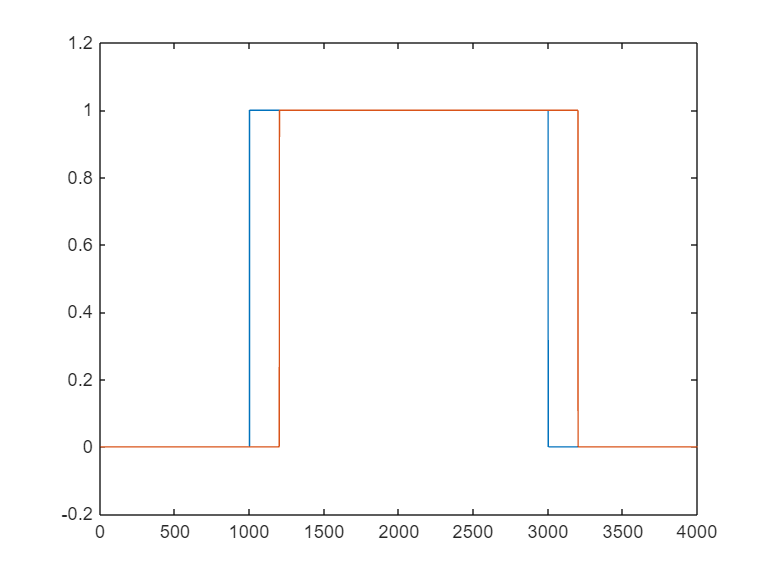

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
veloc = 1000;
l = 50;
fftn = fft.veloc(veloc, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

### SEGUNDO USO, con distorsión de fase, frecuencia de corte 0.0015

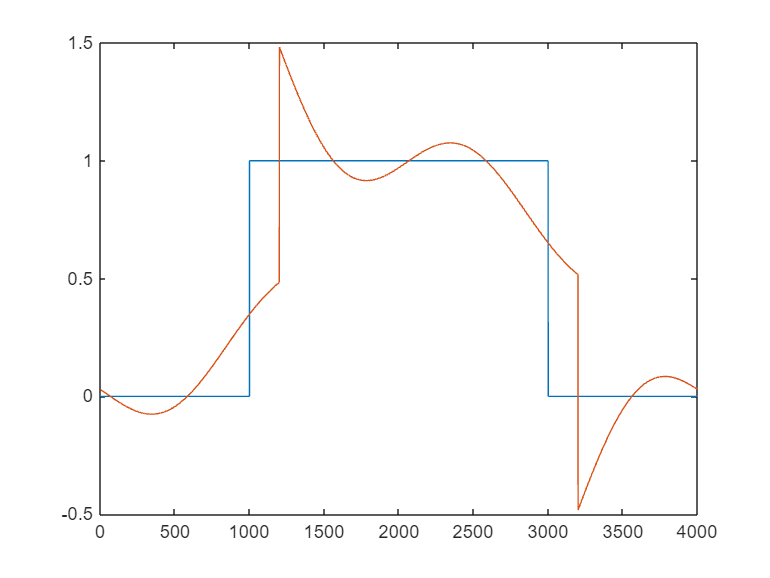

x = [zeros(1, 1000), ones(1, 2000), zeros(1,1000)];
fft = Fftreal(x);
freq = fft.freq();
veloc = 1000*freq./real(sqrt(-freq(3)^2 + freq.^2));
l = 50;
fftn = fft.veloc(veloc, l);
fft.plotx; hold on
fftn.plotx; hold off; legend(["Original", "Propagada"])

## EJERCICIO 4 DEL BOLETÍN 2

### a)

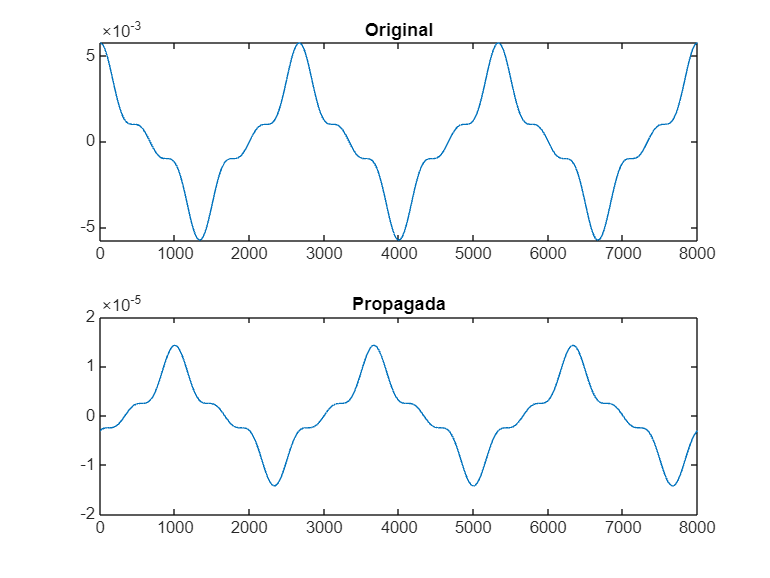

f = [zeros(1, 4000)];
f(3) = 15;
f(9) = 5;
f(15) = 3;
fft = Fftreal([], f);
fftn = fft.alfa(0.06, 100);
fftn = fftn.veloc(800, 100);
subplot(2, 1, 1); plot(fft.x); title("Original")
subplot(2, 1, 2); plot(fftn.x); title("Propagada")

### b)

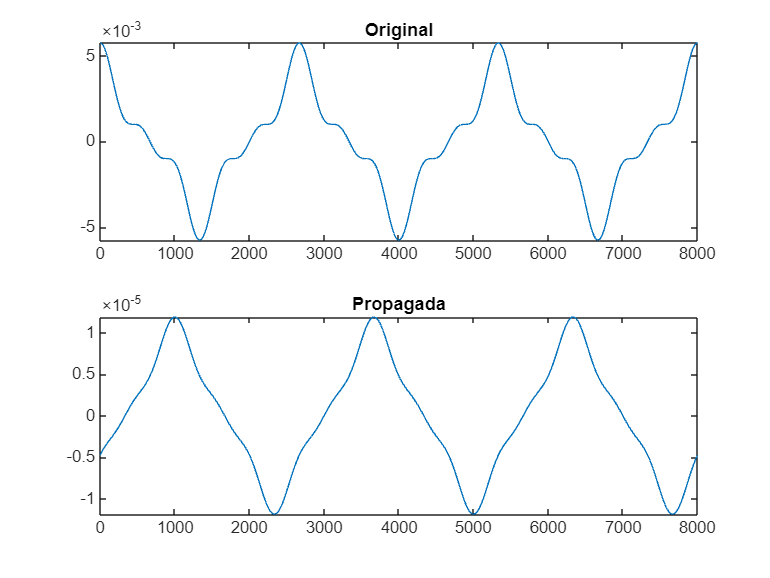

f = [zeros(1, 4000)];
f(3) = 15;
f(9) = 5;
f(15) = 3;
fft = Fftreal([], f);
alfa = zeros(size(fft.freq));
alfa(3) = 0.06;
alfa(9) = 0.065;
alfa(15) = 0.07;
fftn = fft.alfa(alfa, 100);
fftn = fftn.veloc(800, 100);
subplot(2, 1, 1); plot(fft.x); title("Original")
subplot(2, 1, 2); plot(fftn.x); title("Propagada")

### c)

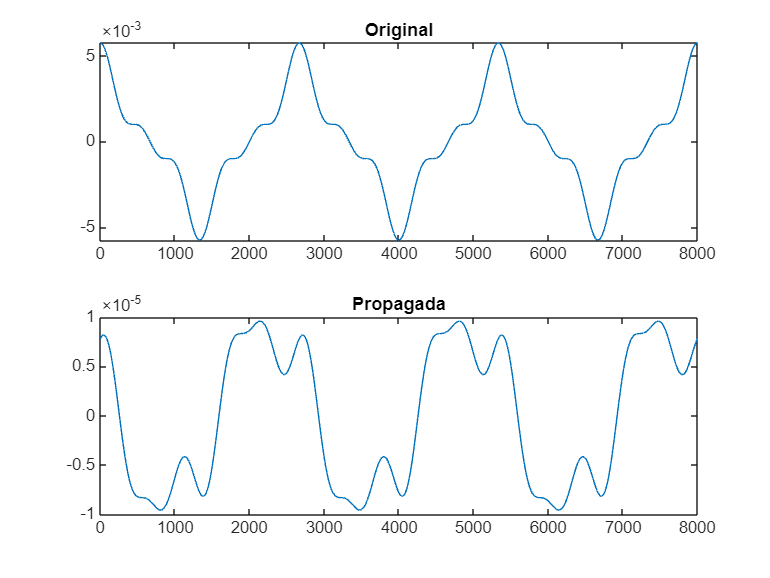

f = [zeros(1, 4000)];
f(3) = 15;
f(9) = 5;
f(15) = 3;
fft = Fftreal([], f);
fftn = fft.alfa(0.06, 100);
veloc = ones(size(fft.freq));
veloc(3) = 360;
veloc(9) = 800;
veloc(15) = 1290;
fftn = fftn.veloc(veloc, 100);
subplot(2, 1, 1); plot(fft.x); title("Original")
subplot(2, 1, 2); plot(fftn.x); title("Propagada")

### d)

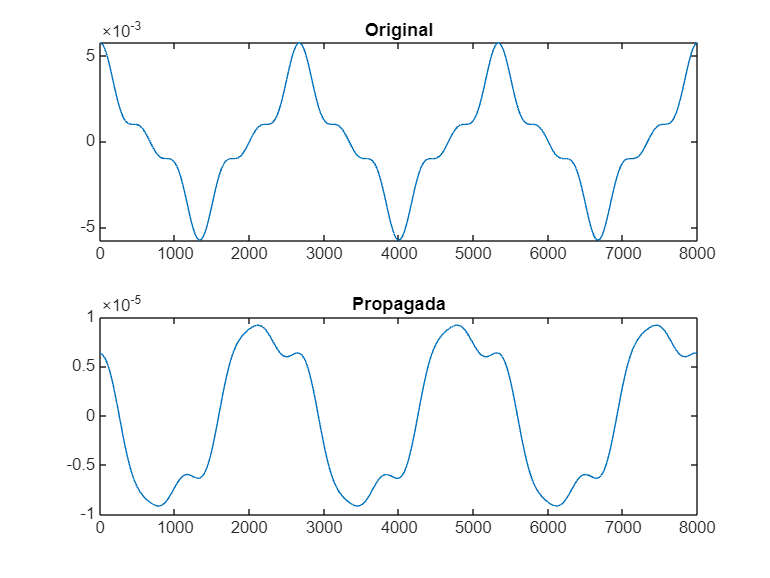

f = [zeros(1, 4000)];
f(3) = 15;
f(9) = 5;
f(15) = 3;
fft = Fftreal([], f);
alfa = zeros(size(fft.freq));
alfa(3) = 0.06;
alfa(9) = 0.065;
alfa(15) = 0.07;
fftn = fft.alfa(alfa, 100);
veloc = ones(size(fft.freq));
veloc(3) = 360;
veloc(9) = 800;
veloc(15) = 1290;
fftn = fftn.veloc(veloc, 100);
subplot(2, 1, 1); plot(fft.x); title("Original")
subplot(2, 1, 2); plot(fftn.x); title("Propagada")